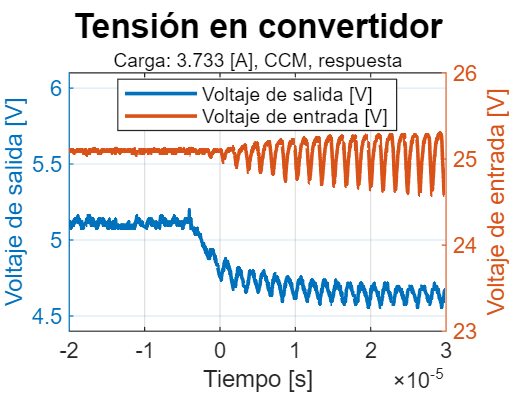

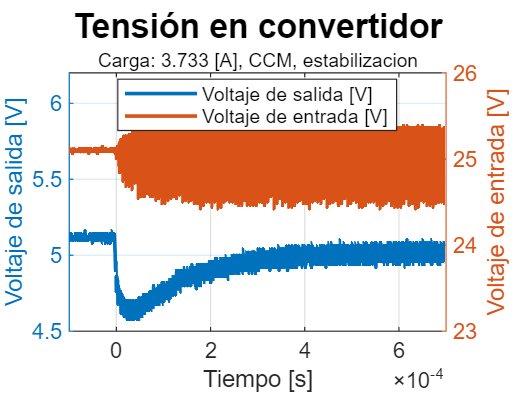

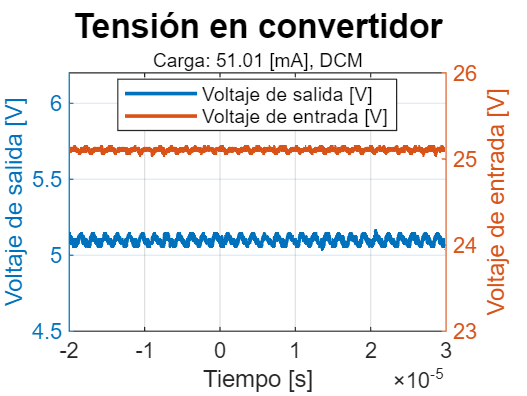

clf;
clc;
clear all;

%Inputs
data = ["2025-12-12_convertidores3/scope_29.csv", "2025-12-12_convertidores3/scope_24.csv", "2025-12-12_convertidores3/scope_38.csv"];
labels1 = {"Tiempo [s]", "Voltaje de salida [V]", "Voltaje de entrada [V]", "Tensión en convertidor", "Carga: 3.733 [A], CCM, respuesta"};
labels2 = {"Tiempo [s]", "Voltaje de salida [V]", "Voltaje de entrada [V]", "Tensión en convertidor", "Carga: 3.733 [A], CCM, estabilizacion"};
labels3 = {"Tiempo [s]", "Voltaje de salida [V]", "Voltaje de entrada [V]", "Tensión en convertidor", "Carga: 51.01 [mA], DCM"};
labels = {labels1, labels2, labels3};


limits1 = [-2e-5,3e-5 , 4.4,6.1 , 23,26]; %NaN por axis for auto 
limits2 = [-1e-4,7e-4 , 4.5,6.2 , 23,26]; %NaN por axis for auto 
limits3 = [NaN,NaN , 4.5,6.2 , 23,26]; %NaN por axis for auto 
limits = {limits1, limits2, limits3};

outputName = ["Figuras/buck_ccm_rpta.png", "Figuras/buck_ccm_2ss.png", "Figuras/buck_dcm.png"];

%Fun Fcall
for i = 1:1:3
    plot_scope_data_conv(data(i), labels{i}, limits{i}, outputName(i));
end


dv = 5 - 3.3;
ix = 0.636;
pot_dis = dv*ix

pot_dis = 1.0812

pot_sum = 5*ix

pot_sum = 3.1800


eff = (3.3/5)

eff = 0.6600

# LDO

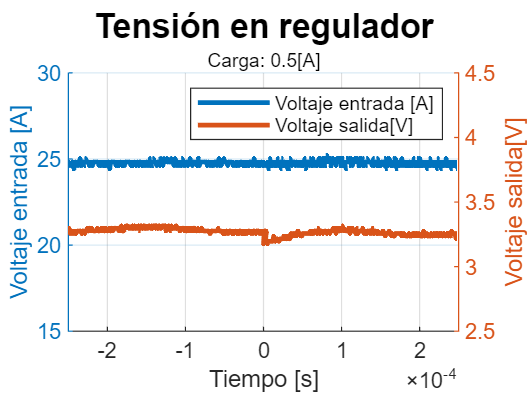

clf


data = readmatrix("2025-12-11_convertidores2/scope_23.csv", 'NumHeaderLines', 2);
time_1      = data(:, 1);
volt_1      = data(:, 2);
volt_2      = data(:, 3);

clf %% clean figure

figure(13)
hold on 
grid on

yyaxis right
plot(time_1,volt_1,'LineStyle', '-', 'LineWidth', 2)
ylim([2.5 4.5]);
ylabel("Voltaje salida[V]");

yyaxis left
plot(time_1,volt_2,'LineStyle', '-', 'LineWidth', 2)
ylim([15 30]);
ylabel("Voltaje entrada [A]");


xlabel("Tiempo [s]");
xlim([-0.25e-3 0.25e-3])
title('Tensión en regulador','FontSize',14);
subtitle('Carga: 0.5[A]','FontSize',8);
legend({'Voltaje entrada [A]', 'Voltaje salida[V]'}, 'Location', 'northeast');
hold off


exportgraphics(gcf,"Figuras/ldo_rpta.png");